# Práctica 2. Filtros FIR e IIR

#### **Ejercicio 4**

**a) **Genera 20 segundos de la siguiente señal (con ω=2rad/s) y represéntala en el dominio del tiempo y de la frecuencia (hecho ya en la práctica 2): 

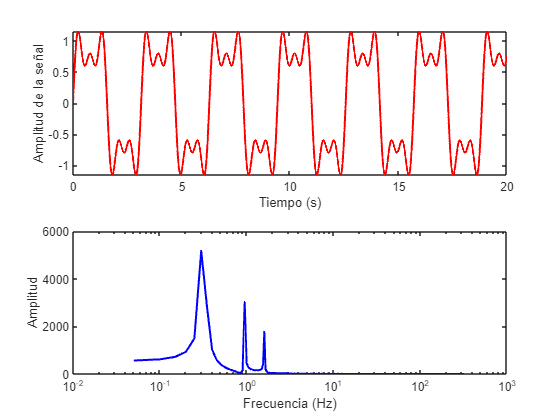

% Parámetros de la señal
clear all
close all

w = 2; % Frecuencia angular en rad/s
fs = 2000*w/(2*pi); % Frecuencia de muestreo en Hz (x1000 frec de la señal)
t = 0:1/fs:20; % Vector de tiempo de 0 a 20 segundos con paso de 1/fs

% Señal original
y = sin(w*t) + 0.5*sin(3*w*t) + 0.3*sin(5*w*t);
%FFT
fft_y=abs(fft(y));
n=length(y);
freq=linspace(0,fs/2,n/2+1);
fft_y=fft_y(1:length(freq));

figure(1)
subplot(2,1,1)
plot(t,y,'r','LineWidth',1.5);
ylabel('Amplitud de la señal')
xlabel('Tiempo (s)')
subplot(2,1,2)
semilogx(freq,fft_y,'b','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')

**b)** Extrae cada una de las tres componentes usando el filtro IIR que corresponda (paso bajo, paso alto, paso banda o supresor de banda). Elige en cada caso el filtro digital más apropiado (Butterworth, Chebychev 1, Chebychev 2 o Elíptico). 

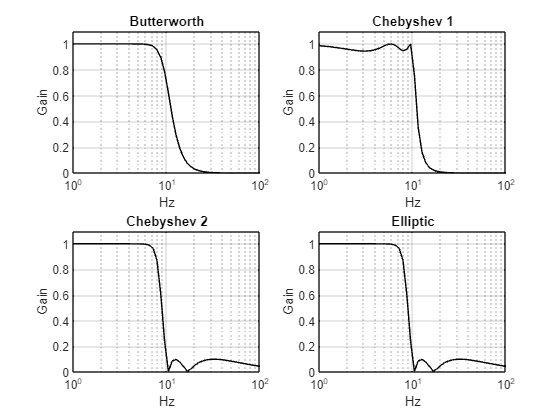

fc=10/fs*2;
N=5; %order of the filter
Rp=0.5; %decibels of ripple in the pass band
Rs=20; %decibels of ripple in the stop band

[numd, dend]=butter (N, fc); %digital Butterworth filter
F=logspace (0,2); %logaritmic set of frequency values in Hz 
G=freqz (numd, dend, F, fs); %computes frequency response
subplot (2,2,1); semilogx (F, abs (G),'k'); %plots linear amplitude 
axis ([1 100 0 1.1]); grid;
ylabel('Gain'); xlabel('Hz'); title ('Butterworth');

[numd, dend]=cheby1 (N, Rp, fc); %digital Chebyshev 1 filter 
G=freqz (numd, dend, F, fs); %computes frequency response
subplot (2,2,2); semilogx (F, abs (G),'k'); %plots linear amplitude 
axis ([1 100 0 1.1]); grid;
ylabel('Gain'); xlabel('Hz'); title('Chebyshev 1');

[numd, dend]=cheby2 (N, Rs, fc); %digital Chebyshev 2 filter
G=freqz (numd, dend, F, fs); %computes frequency response
subplot (2,2,3); semilogx (F, abs (G), 'k'); %plots linear amplitude 
axis ([1 100 0 1.1]); grid;
ylabel('Gain'); xlabel('Hz'); title('Chebyshev 2');

[numd, dend]=ellip (N, Rp, Rs, fc); %digital elliptic filter G=freqz (numd, dend, F, fs); %computes frequency response 
subplot (2,2,4); semilogx (F, abs (G), 'k'); %plots linear amplitude 
axis ([1 100 0 1.1]); grid; ylabel('Gain'); xlabel('Hz'); title('Elliptic');

Representa cada componente extraída en el domino del tiempo y de la frecuencia, además de la respuesta en frecuencia del filtro empleado (ganancia y fase). Emplea el comando “filtfilt()”para aplicar los filtros .

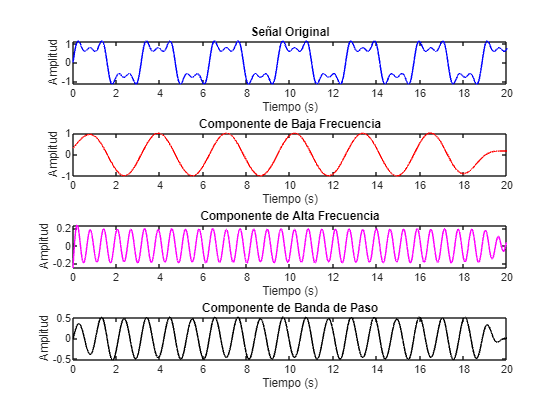


% Filtro paso bajo
fc_low = 0.5; % Frecuencia de corte para el filtro paso bajo
order_low = 5; % Orden del filtro
[b_low, a_low] = butter(order_low, fc_low/(fs/2), 'low');

% Filtro paso alto
fc_high = 1.5; % Frecuencia de corte para el filtro paso alto
order_high = 5; % Orden del filtro
[b_high, a_high] = butter(order_high, fc_high/(fs/2), 'high');

% Filtro paso banda
fc_band = [0.5, 1.25]; % Frecuencia de corte para el filtro paso banda
order_band = 3; % Orden del filtro
[b_band, a_band] = butter(order_band, fc_band/(fs/2), 'bandpass');
% Aplicar los filtros a la señal original

y_low = filtfilt(b_low, a_low, y);
y_high = filtfilt(b_high, a_high, y);
y_band = filtfilt(b_band, a_band, y);

% Representación en el dominio del tiempo
figure(2);

subplot(4,1,1);
plot(t, y,'b');
title('Señal Original');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(4,1,2);
plot(t, y_low,'r');
title('Componente de Baja Frecuencia');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(4,1,3);
plot(t, y_high,'m');
title('Componente de Alta Frecuencia');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(4,1,4);
plot(t, y_band,'k');
title('Componente de Banda de Paso');
xlabel('Tiempo (s)');
ylabel('Amplitud');               

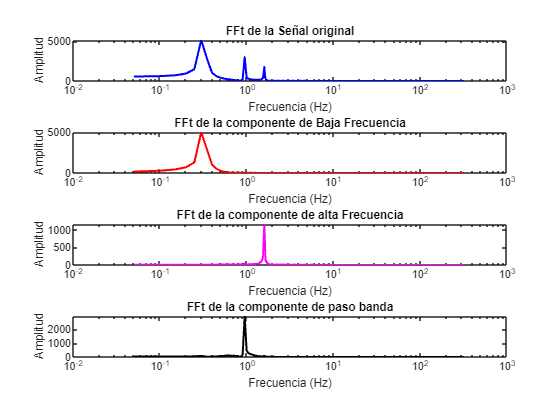

%Representación en el dominio de la frecuencia
y_low_fft=abs(fft(y_low));
y_low_fft=y_low_fft(1:length(freq));

y_band_fft=abs(fft(y_band));
y_band_fft=y_band_fft(1:length(freq));

y_high_fft=abs(fft(y_high));
y_high_fft=y_high_fft(1:length(freq));

figure(3)
subplot(4,1,1)
semilogx(freq,fft_y,'b','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')
title('FFt de la Señal original');

subplot(4,1,2)
semilogx(freq,y_low_fft,'r','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')
title('FFt de la componente de Baja Frecuencia');

subplot(4,1,3)
semilogx(freq,y_high_fft,'m','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')
title('FFt de la componente de alta Frecuencia');

subplot(4,1,4)
semilogx(freq,y_band_fft,'k','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')
title('FFt de la componente de paso banda');

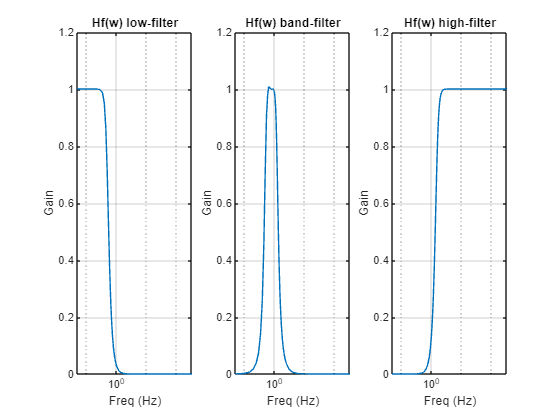

%%Ahora vamos con la respuesta del filtro
figure(4)

subplot(1,3,1)
f=logspace(-1,1);
low_filt=freqz(b_low,a_low,freq,fs);%NOs da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(freq,abs(low_filt)); %Representación usando eje x logarítimico
grid;
ylabel('Gain')
xlabel('Freq (Hz)')
title('Hf(w) low-filter')

subplot(1,3,2)
band_filt=freqz(b_band,a_band,freq,fs);%NOs da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(freq,abs(band_filt)); %Representación usando eje x logarítimico
grid;
ylabel('Gain')
xlabel('Freq (Hz)')
title('Hf(w) band-filter')

subplot(1,3,3)
high_filt=freqz(b_high,a_high,freq,fs);%NOs da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(freq,abs(high_filt)); %Representación usando eje x logarítimico
grid;
ylabel('Gain')
xlabel('Freq (Hz)')
title('Hf(w) high-filter')

**c)** Por último, reconstruye la señal y(t) sumando las tres señales extraídas. Muestra el resultado

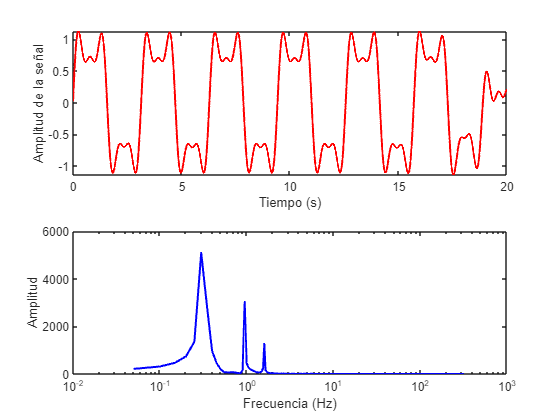

y_rec=y_low+y_band+y_high;
fft_y_rec=abs(fft(y_rec));
fft_y_rec=fft_y_rec(1:length(freq));
figure(5)
subplot(2,1,1)
plot(t,y_rec,'r','LineWidth',1.5);
ylabel('Amplitud de la señal')
xlabel('Tiempo (s)')
subplot(2,1,2)
semilogx(freq,fft_y_rec,'b','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')

**d)** Repite los apartados **b)** y **c) **empleando el comando “filter()” para aplicar los filtros.

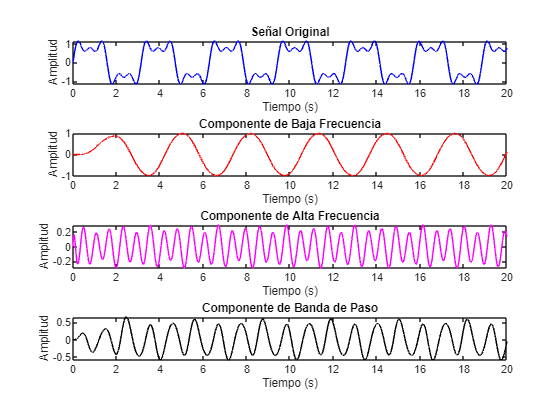

% Aplicar los filtros a la señal original
y_low_2 = filter(b_low, a_low, y);
y_high_2 = filter(b_high, a_high, y);
y_band_2 = filter(b_band, a_band, y);

% Representación en el dominio del tiempo
% Representación en el dominio del tiempo
figure(6);

subplot(4,1,1);
plot(t, y,'b');
title('Señal Original');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(4,1,2);
plot(t, y_low_2,'r');
title('Componente de Baja Frecuencia');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(4,1,3);
plot(t, y_high_2,'m');
title('Componente de Alta Frecuencia');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(4,1,4);
plot(t, y_band_2,'k');
title('Componente de Banda de Paso');
xlabel('Tiempo (s)');
ylabel('Amplitud');  

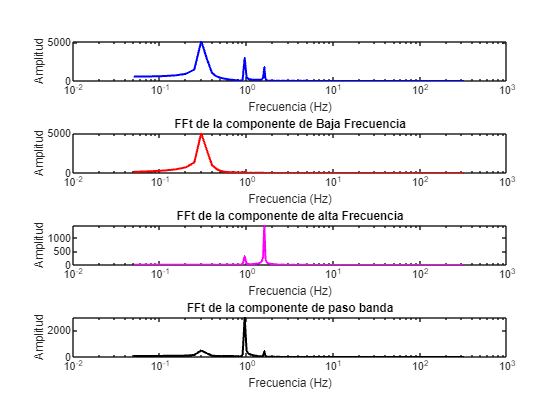

%Representación en el dominio de la frecuencia
y_low_fft_2=abs(fft(y_low_2));
y_low_fft_2=y_low_fft_2(1:length(freq));

y_band_fft_2=abs(fft(y_band_2));
y_band_fft_2=y_band_fft_2(1:length(freq));

y_high_fft_2=abs(fft(y_high_2));
y_high_fft_2=y_high_fft_2(1:length(freq));

figure(7)
subplot(4,1,1)
semilogx(freq,fft_y,'b','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')
subplot(4,1,2)
semilogx(freq,y_low_fft_2,'r','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')
title('FFt de la componente de Baja Frecuencia');
subplot(4,1,3)
semilogx(freq,y_high_fft_2,'m','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')
title('FFt de la componente de alta Frecuencia');
subplot(4,1,4)
semilogx(freq,y_band_fft_2,'k','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')
title('FFt de la componente de paso banda');

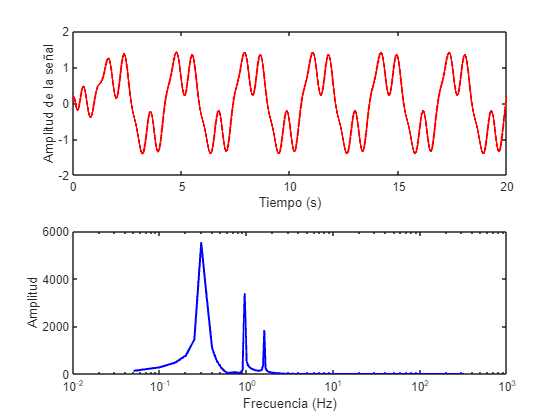

%%Reconstruimos 
y_rec_2=y_low_2+y_band_2+y_high_2;
fft_y_rec_2=abs(fft(y_rec_2));
fft_y_rec_2=fft_y_rec_2(1:length(freq));
figure(8)
subplot(2,1,1)
plot(t,y_rec_2,'r','LineWidth',1.5);
ylabel('Amplitud de la señal')
xlabel('Tiempo (s)')
subplot(2,1,2)
semilogx(freq,fft_y_rec_2,'b','LineWidth',1.5)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud')